# **디지털신호처리 ****HW#1**

Due date : 2021.10.21. 23:59

**이름**** : 고상훈**

**학번**** : 201710868**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 다음 신호를 stem 함수를 이용하여 그려라.

1) 

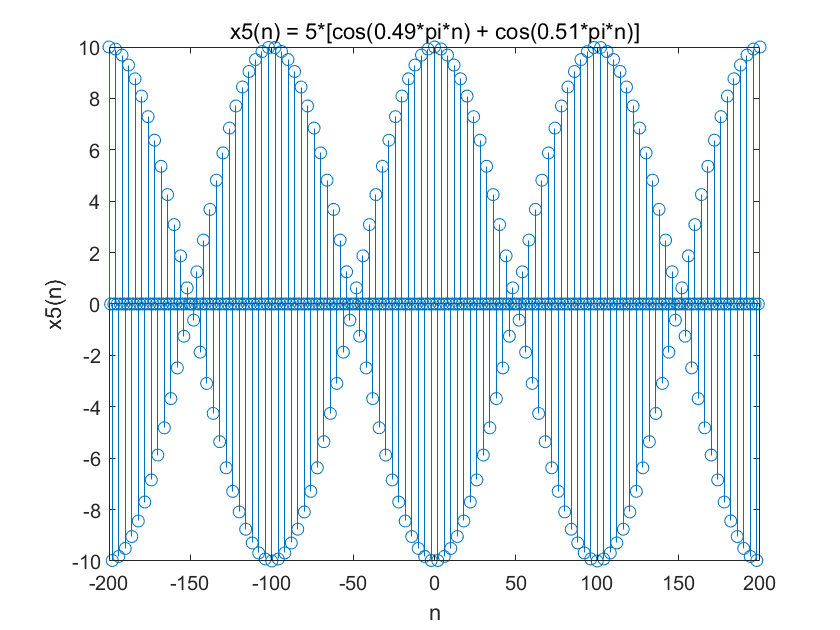

n = -200:200;
x5 = 5*(cos(0.49*pi*n) + cos(0.51*pi*n));
stem(n, x5);
title('x5(n) = 5*[cos(0.49*pi*n) + cos(0.51*pi*n)]')
xlabel('n'); ylabel('x5(n)');

2) 

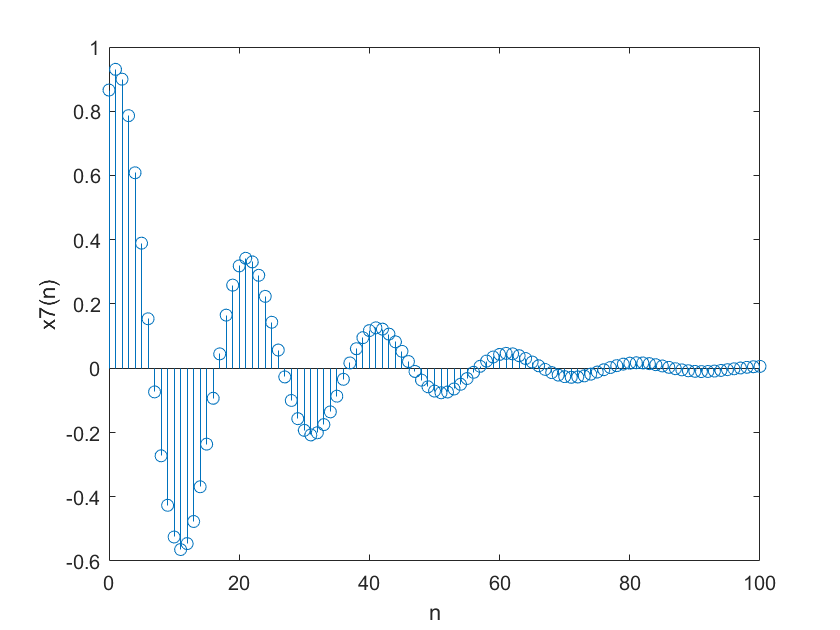

clear all;

n = 0:100;
x7 = exp(-0.05*n).*sin(0.1*pi*n + pi/3);
stem(n,x7);
xlabel('n'); ylabel('x7(n)');

2.  (P2.16) LTI 시스템의 차분 방정식이 다음과 같다.


$$y\left(n\right)-0\ldotp 5y\left(n-1\right)+0\ldotp 25y\left(n-2\right)=x\left(n\right)+2x\left(n-1\right)+x\left(n-3\right)$$


1) MATLAB의 impz 함수를 사용하여 0<=n<=100 구간에서 시스템의 임펄스 응답을 구하고 stem을 이용해서 그려라.

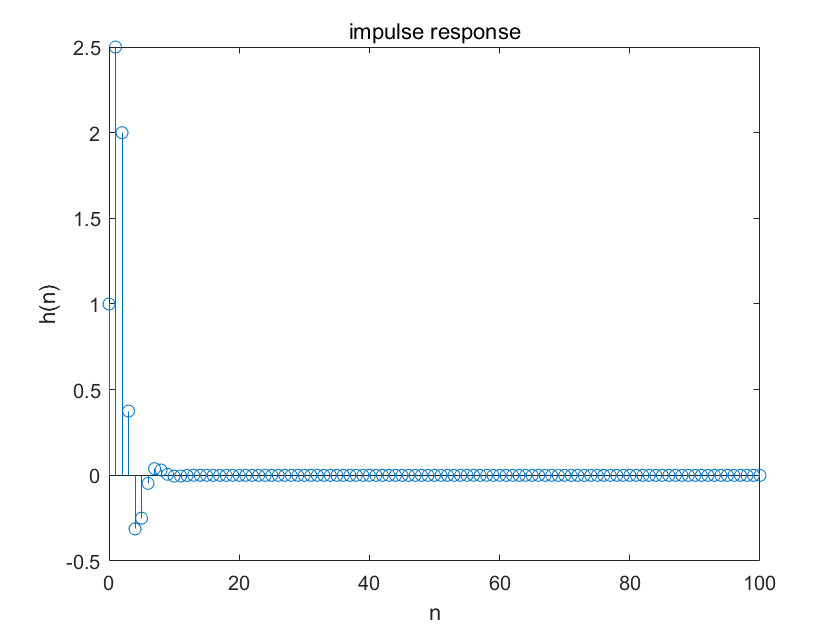

b = [1,2,1];
a = [1,-0.5,0.25];
n = 0:100;
h = impz(b,a,n);
stem(n,h);
title('impulse response');
xlabel('n');
ylabel('h(n)');

2) 이 임펄스 응답으로부터 안정성을 판별하라. (sum, abs 함수 사용)

sum(abs(h))

ans = 6.5714

이는 시스템이 안정함을 보여준다!

3) 만약 이 시스템의 입력이  이면, filter 함수를 사용하여0<=n<=200 구간에서 응답 y(n)을 구하라.

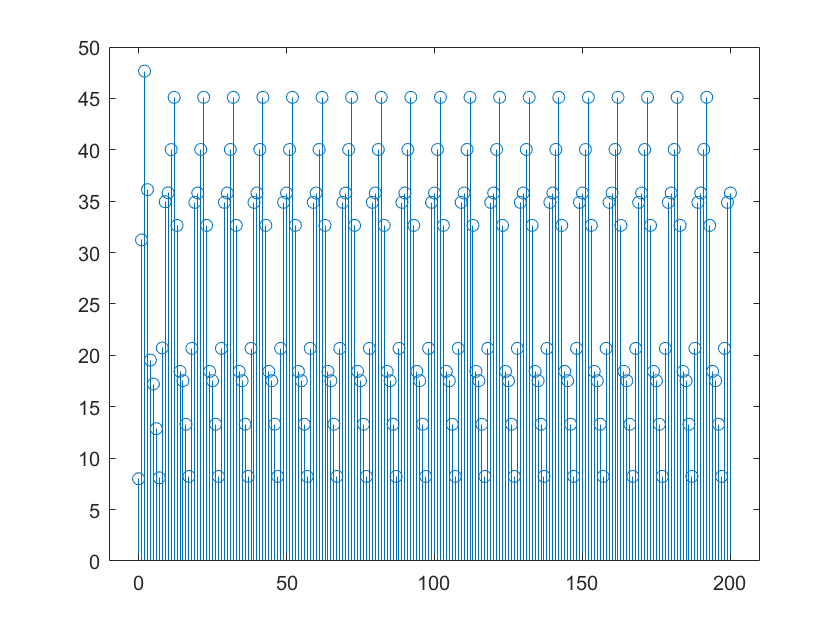

% 입력 : x(n) = [5+3*cos(0.2*pi*n)+4*sin(0.6*pi*n)]*u(n)
n = 0:200;
x = [5+3*cos(0.2*pi*n)+4*sin(0.6*pi*n)].*stepseq(0,0,200);
y = filter(b,a,x);
stem(n,y);
axis([-10 210 0 50]);

3. (P2.20) 

일 때, 다음을 그려라. 

1) y(n)의 처음 51개 샘플을 stem 함수 이용해서 그려라. 

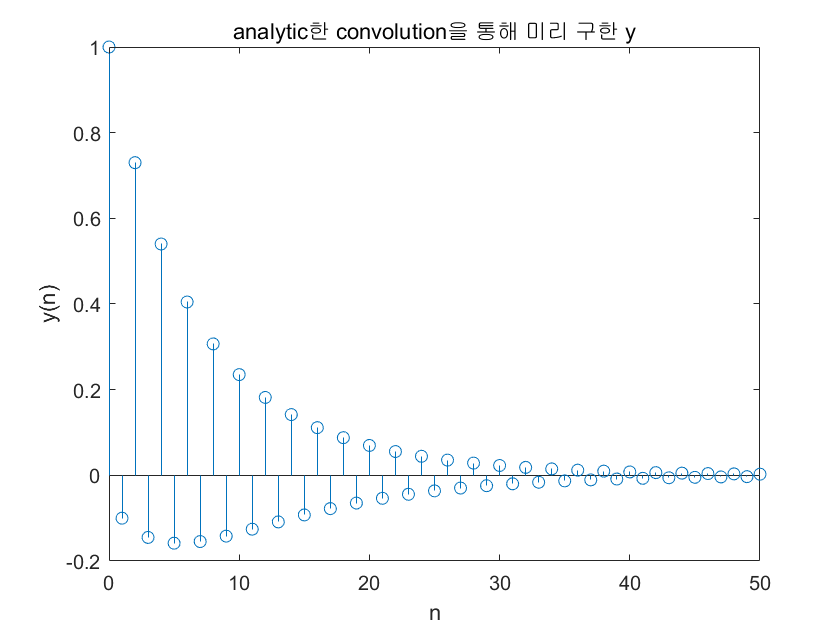

% 이는 conv함수를 이용하지 않는 방식이기 때문에 convolution을 따로 계산한 이후에 stem으로서 도사하여야한다.
% convolution의 정의로서 시행하여 구한 y(n) = ((0.8).^(n+1) - (-0.9).^(n+1))/(0.8+0.9)
n = 0:50;
Yanalatic = ((0.8).^(n+1) - (-0.9).^(n+1))/(0.8+0.9);
stem(n,Yanalatic);
title('analytic한 convolution을 통해 미리 구한 y');
xlabel('n');
ylabel('y(n)');

2) x(n)과 h(n)을 26개의 샘플이 되도록 자른뒤, conv 함수를 이용해서 y(n)을 구하고 stem 이용해서 그려라. 

이는 conv를 실행하기 전에 x와 h를 26개의 샘플로 잘라주는 과정을 거쳐야한다

그것에 이용되는 것이 x(1:26)이다. 이는 총 51개의 샘플로 구성되어있는 x를 26개의 샘플로 분리하는 역할을 한다.

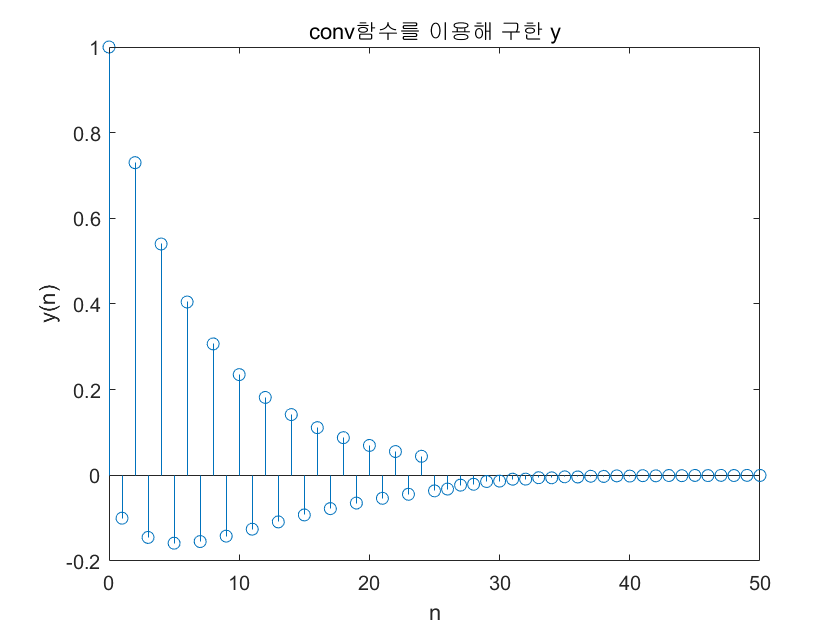

n = 0:50;
x = ((0.8).^n).*stepseq(0,0,50);
h = ((-0.9).^n).*stepseq(0,0,50);
x = x(1:26); % x를 26개의 샘플로 분리함
h = h(1:26); % y를 26개의 샘플로 분리함
y = conv(x,h);
stem(n,y);
title('conv함수를 이용해 구한 y');
xlabel('n');
ylabel('y(n)');

3) filter 함수를 이용해서 $x\left(n\right)\ast h\left(n\right)$의 처음 51개 샘플을 구하고 stem 이용해서 그려라. 

<풀이>

(-0.9)*h(n-1) = (-0.9)*((-0.9)^(n-1))*u(n-1) = ((-0.9)^n) * u(n-1) 이고,

h(n) - (-0.9)*h(n-1) = ((-0.9)^n) * u(n) - ((-0.9)^n) * u(n-1)

= ((-0.9)^n) * ( u(n) - u(n-1)) = ((-0.9)^n)* delta(n)

= delta(n)

고로 -> h(n) + 0.9 * h(n-1) = delta(n) 이다.

정의에 따르면 h(n)은 입력이 delta(n)일 때 LTI시스템의 출력이다.

고로 delta -> x , h -> y 로서 치환하면 차분방정식을 구할 수 있다.

차분 방정식 :  y(n) + 0.9 * y(n-1) = x(n)

이를 filter를 통해서 간접적으로 컨벌루션을 구해줄 수 있다.

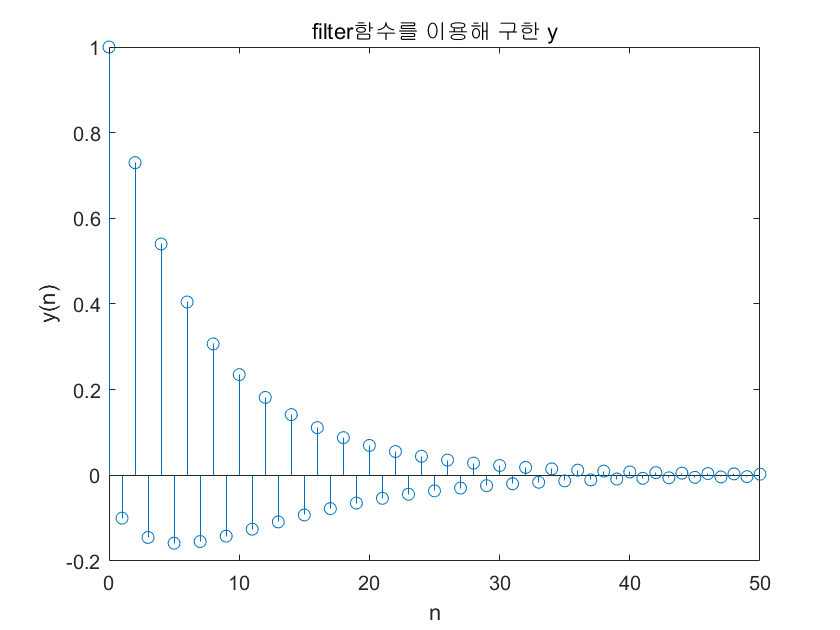

clear all
a = [1]; % 배열으로 우변을 나타내고 있다.
b = [1,0.9]; % 배열으로 좌변을 나타내고 있다.
n = 0:50;
x = ((0.8).^n).*stepseq(0,0,50);
y1 = filter(a,b,x);
% filter는 차분방정식을 통해 x를 통한 y의 값을 보여줄 수 있다.
stem(n,y1);
title('filter함수를 이용해 구한 y');
xlabel('n');
ylabel('y(n)');

4. (P3.14) 임펄스 응답으로 기술된 각 선형 시불변 시스템에 대해 구간 $\left\lbrack -\pi ,\pi \right\rbrack$에서 주파수 응답 함수 $H\left(e^{j\omega } \right)$을 구하고 크기 응답과 위상 응답을 그려라. 

1) $h\left(n\right)={\left(0\ldotp 9\right)}^{|n|}$

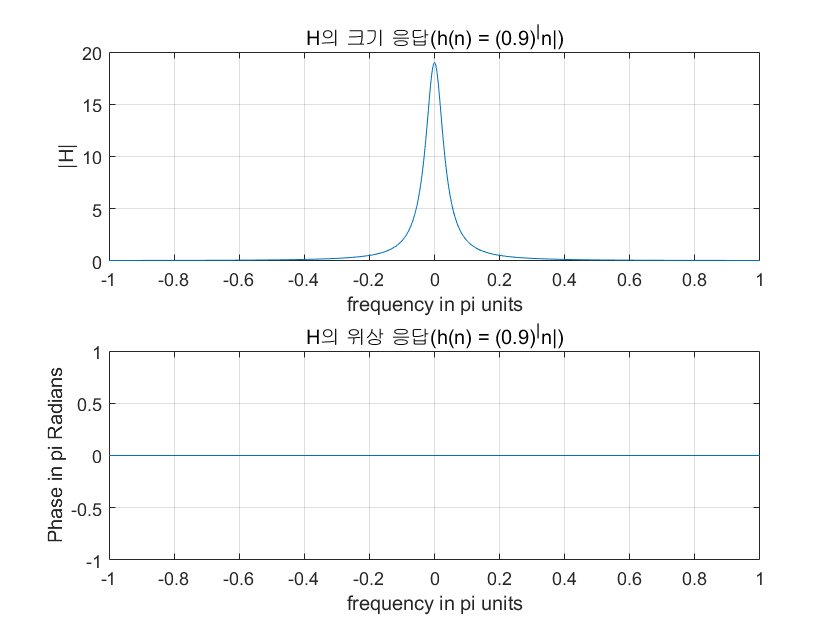

w = [-500:500]*pi/500; % [-pi:pi] 를 1001개의 점으로 나누었다.
% 식을 이용하면 H(exp(j*w)) = 0.19/(1.81-1.8*cos(w))가 된다.
H = 0.19*ones(1,1001)./(1.81-1.8*cos(w));
% 행렬의 차원을 일치시키기 위하여 ones를 사용하였다.
magH = abs(H);
angH = angle(H)*180/pi; % radian으로 위상의 단위를 바꾸어준것!
figure()
subplot(2,1,1), plot(w/pi,magH);
title('H의 크기 응답(h(n) = (0.9)^|n|)');
xlabel('frequency in pi units');
ylabel('|H|');
grid on;

subplot(2,1,2), plot(w/pi,angH);
title('H의 위상 응답(h(n) = (0.9)^|n|)');
xlabel('frequency in pi units');
ylabel('Phase in pi Radians');
grid on;

2) $h\left(n\right)=\left\lbrack {\left(0\ldotp 5\right)}^n +{\left(0\ldotp 4\right)}^n \right\rbrack u\left(n\right)$

H를 계산하면 H = 1/(1-0.5*exp(-j*w)) + 1/(1-0.4*exp(-j*w)) 이다.

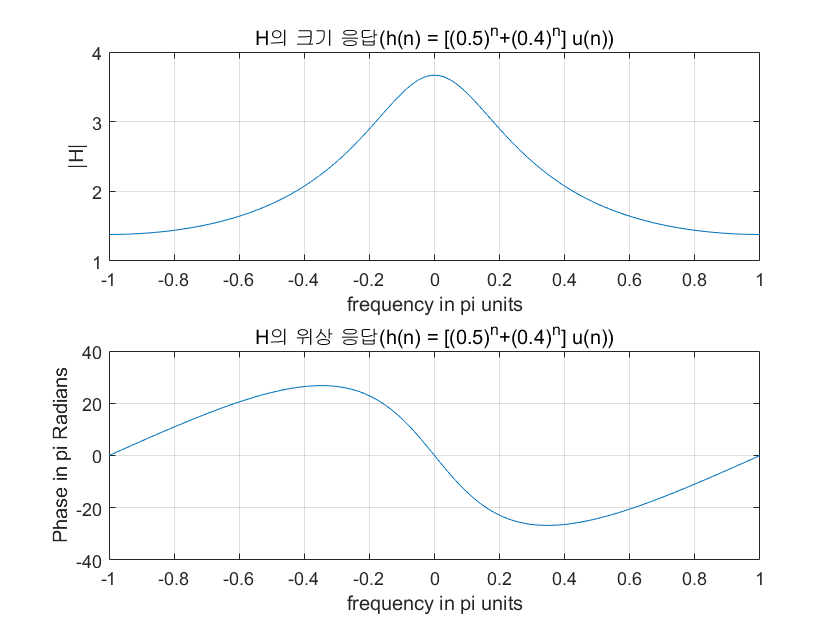

clear all
w1 = [-500:500]*pi/500;
% H를 계산하면  1/(1-0.5*exp(-j*w)) + 1/(1-0.4*exp(-j*w)) 이기에 이를 표현하였다.
H1 = exp(j*w1)./(exp(j*w1)-0.5*ones(1,1001)) + exp(j*w1)./(exp(j*w1)-0.4*ones(1,1001));
magH = abs(H1);
angH = angle(H1)*180/pi;

figure()
subplot(2,1,1), plot(w1/pi,magH);
title('H의 크기 응답(h(n) = [(0.5)^n+(0.4)^n] u(n))');
xlabel('frequency in pi units');
ylabel('|H|');
grid on;

subplot(2,1,2), plot(w1/pi,angH);
title('H의 위상 응답(h(n) = [(0.5)^n+(0.4)^n] u(n))');
xlabel('frequency in pi units');
ylabel('Phase in pi Radians');
grid on;

5. (P3.17) 

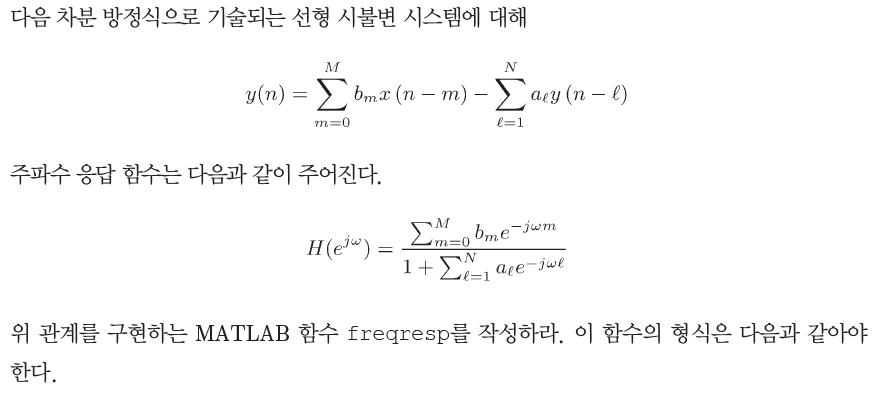

% freqresp는 110번-125행에 정의되어 있습니다.

저는 6번문제에 이 freqresp를 적용하여 구해보기 위하여 함수를 맨 아래로 내려 사용할 수 있도록 하였습니다.

6. (P3.19) 다음의 각 시스템에 대해 $H\left(e^{j\omega } \right)$을 구하고, 그 크기와 위상을 그려라

1) $y\left(n\right)=x\left(n\right)-x\left(n-2\right)+0\ldotp 95y\left(n-1\right)-0\ldotp 9025y\left(n-2\right)$

넘길것을 넘겨보면 차분방정식은

$y\left(n\right)-0\ldotp 95y\left(n-1\right)+0\ldotp 9025y\left(n-2\right)=x\left(n\right)-x\left(n-2\right)$ 이와 같이 표시된다!

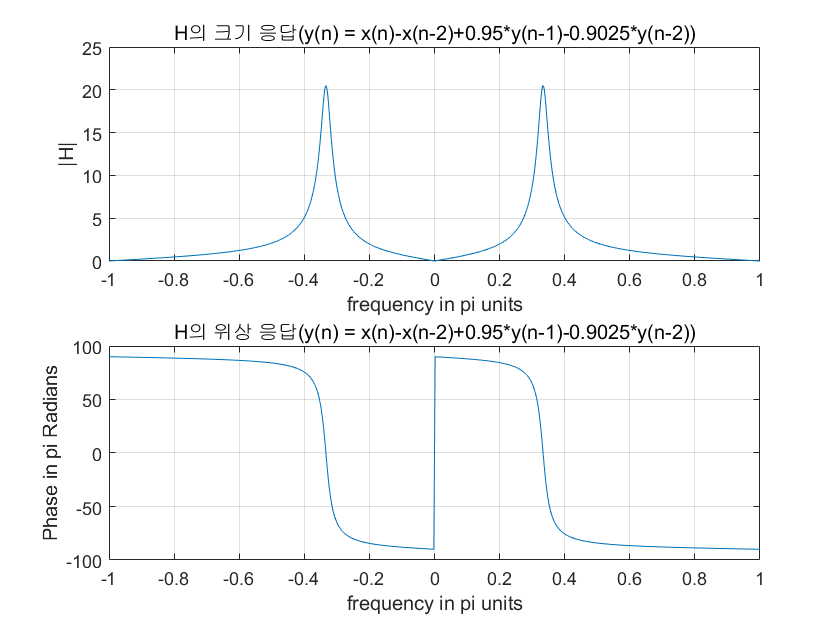

clear all;
% 5번 문제에서 만든 함수를 이용해보자!
w = [-500:500]*pi/500;
a = [1, -0.95, 0.9025];
b = [1, 0, -1];
[H] = freqresp(b,a,w); % 만든 함수를 이용해보자!
magH = abs(H);
angH = angle(H)*180/pi;

% 앞에서 해결했던 문제와 동일한 구성이 계속 되었기 때문에
% 위의 문제에서 사용하였던 방식을 사용하였다.

figure()
subplot(2,1,1), plot(w/pi,magH);
title('H의 크기 응답(y(n) = x(n)-x(n-2)+0.95*y(n-1)-0.9025*y(n-2))');
xlabel('frequency in pi units');
ylabel('|H|');
grid on;

subplot(2,1,2), plot(w/pi,angH);
title('H의 위상 응답(y(n) = x(n)-x(n-2)+0.95*y(n-1)-0.9025*y(n-2))');
xlabel('frequency in pi units');
ylabel('Phase in pi Radians');
grid on;

2) $y\left(n\right)=x\left(n\right)-\sum_{l=1}^5 {\left(0\ldotp 5\right)}^n y\left(n-l\right)$

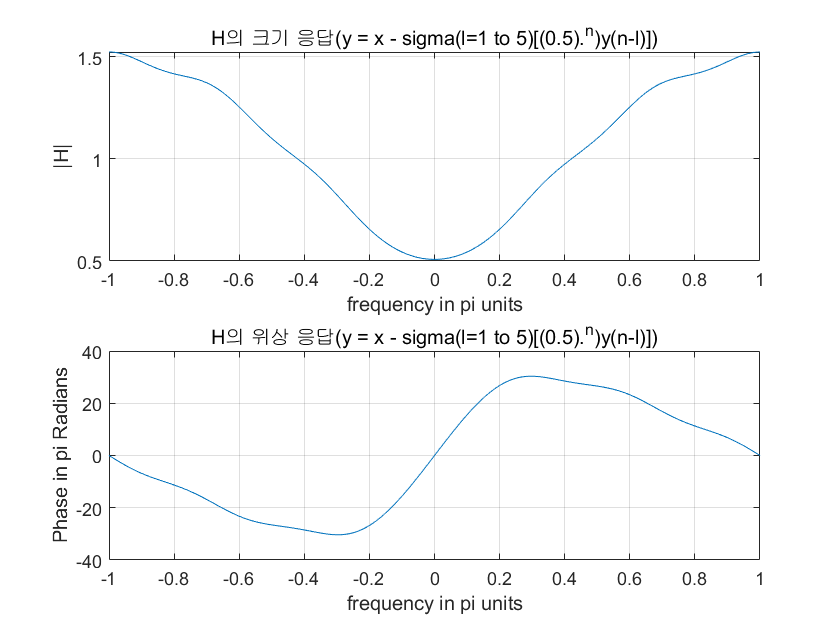

clear all;
w = [-500:500]*pi/500;
a = 0.5.^[0:5]; % 차분방정식에서 y의 계수를 배열로 나타낸 것
b = [1]; % 차분방정식에서 x의 계수
[H] = freqresp(b,a,w); % 마찬가지로 만든 함수를 이용해보자!
magH = abs(H);
angH = angle(H)*180/pi;

% 앞에서 해결했던 문제와 동일한 구성이 계속 되었기 때문에
% 위의 문제에서 사용하였던 방식을 사용하였다.

figure()
subplot(2,1,1), plot(w/pi,magH);
title('H의 크기 응답(y = x - sigma(l=1 to 5)[(0.5).^n)y(n-l)])');
xlabel('frequency in pi units');
ylabel('|H|');
grid on;

subplot(2,1,2), plot(w/pi,angH);
title('H의 위상 응답(y = x - sigma(l=1 to 5)[(0.5).^n)y(n-l)])');
xlabel('frequency in pi units');
ylabel('Phase in pi Radians');
grid on;

% 저는 계단함수를 표현하기 위해서 stepseq라는 사용자함수를 따로 정의하였습니다.

function [x,n] = stepseq(n0,n1,n2);
n = [n1:n2]; x = [(n-n0) >= 0];
end


function [H] = freqresp(b,a,w)
% H = frequency response array evaluated at w frequencies
% b = numerator coefficient array
% a = denominator coefficient array (a(1) = 1)
% w = frequency location array
% 일단 b와 a를 정의하자. b와 a는 각각의 길이를 갖는 배열이고,
% m값에 따라서 바뀌는 값일 것이다.
b = reshape(b,1,length(b)); % b = numerator coefficient array
a = reshape(a,1,length(a)); % a = denominator coefficient array (a(1) = 1)
w = reshape(w,1,length(w)); % w = frequency location array
% 배열을 다시 정의하기 위해서 reshape라는 내장함수를 사용하였다.
% reshape(a,b,c) = a라는 함수를 b:c까지 재배열하는 함수입니다.

m = 0:length(b)-1; % m과 l은 b와 a의 길이이다.
Hb = b*exp(-j*m'*w);
l = 0:length(a)-1;
Ha = a*exp(-j*l'*w);
H = Hb./Ha; 
% 식에서 볼때 l은 1부터 시작하고, 1은 l이 0일때 값과 마찬가지이므로
% 결국 Hb/Ha로서 정의될 수 있습니다.
end